# 性能函数

p=[-1 2 3 4 -5];
a=mae(p);     % 平均绝对误差
aa=sum(abs(p))/length(p);
b=mse(p);     % 均方差
bb=sum(p.^2)/length(p);
[a aa b bb]

ans =      3     3    11    11


## 感知器-手算

clear,clc, close all

n=0.2;                  % 学习率
w=[0,0,0];
P=[ -9,  1, -12, -4,   0, 5;...
    15,  -8,   4,  5,  11, 9];
d=[0,1,0,0,0,1];        % 期望输出

P=[ones(1,6);P];
MAX=20;                 % 最大迭代次数为20次
%% 训练
i=0;
while 1
    v=w*P;
    y=hardlim(v);       % 实际输出
    %更新
    e=(d-y);
    ee(i+1)=mae(e);
    if (ee(i+1)<0.001)   % 判断
        disp('we have got it:');
        disp(w);
        break;
    end
    % 更新权值和偏置
    w=w+n*(d-y)*P';
    
    if (i>=MAX)         % 达到最大迭代次数，退出
        disp('MAX times loop');
        disp(w);
        disp(ee(i+1));
        break;
    end
    i= i+1;
end   % 分类超平面：7x-3.4y-0.4=0

we have got it:


   -0.4000    7.0000   -3.4000



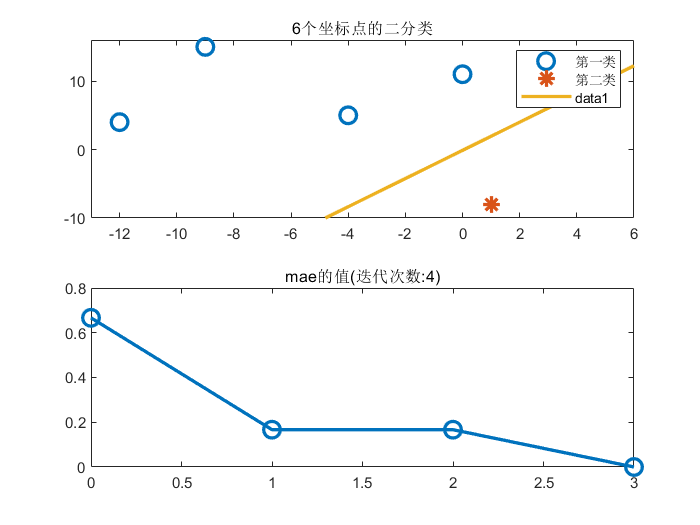



%% 显示
figure;
subplot(2,1,1);         % 显示待分类的点和分类结果
plot([-9 ,  -12  -4    0],[15, 4   5   11],'o','linewidth',2,'markersize',10);
hold on;
plot([1,5],[-8,9],'*','linewidth',2,'markersize',10);
axis([-13,6,-10,16]);
legend('第一类','第二类');
title('6个坐标点的二分类');
x=-13:.2:6;
y=x*(-w(2)/w(3))-w(1)/w(3);
plot(x,y,'linewidth',2);
hold off;

subplot(2,1,2);         % 显示mae值的变化
x=0:i;
plot(x,ee,'o-','linewidth',2,'markersize',10);
s=sprintf('mae的值(迭代次数:%d)', i+1);
title(s);

## 感知器-调用工具箱

clear,clc,close all

% 创建感知器
net=newp([-20,20;-20,20],1);

%定义输入训练向量
P=[ -9,  1, -12, -4,   0, 5;...
    15,  -8,   4,  5,  11, 9];
% 期望输出
T=[0,1,0,0,0,1]

T =      0     1     0     0     0     1



% 训练
net=train(net,P,T);

% 输入训练数据仿真验证
Y=sim(net,P)

Y =      0     1     0     0     0     1


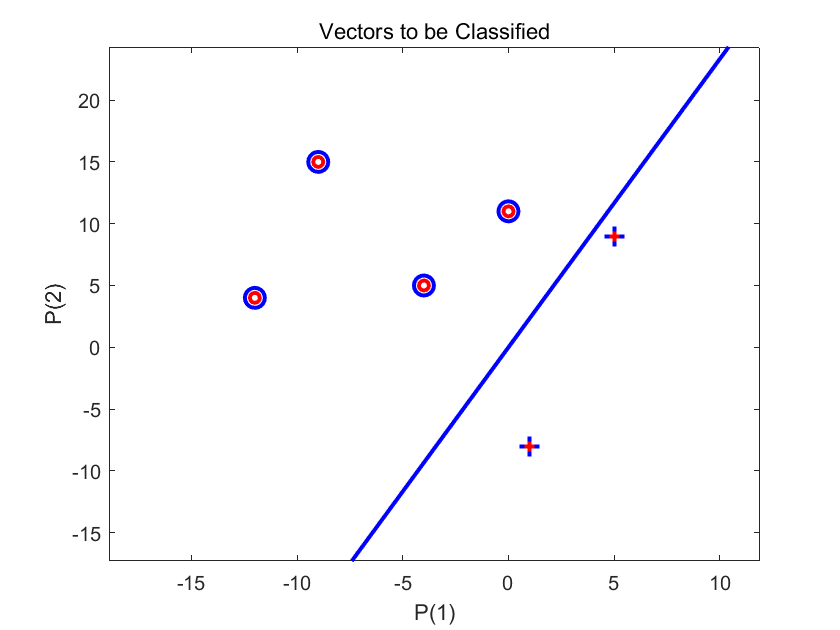


plotpv(P,T);
plotpc(net.IW{1},net.b{1});
hold on;plotpv(P,Y);

h=findobj(gca,'type','line');
set(h,'linewidth',2,'markersize',10)
set(h(1:6),'color','r','markersize',5);

## 线性-手算

clear,clc, close all

%% 定义数据
P=-5:5;                         % 输入：11个标量
d=3*P-7;
% randn('state',2);
d=d+randn(1,length(d))*1.5     % 期望输出：加了噪声的线性函数

d =   -21.1935  -16.2492  -19.3883  -11.7067   -9.5219   -8.9615   -4.6504   -0.4861    7.3676    9.1542    5.9752



P=[ones(1,length(P));P]        % P加上偏置

P =      1     1     1     1     1     1     1     1     1     1     1
    -5    -4    -3    -2    -1     0     1     2     3     4     5


lp.lr = 0.01;                  % 学习率
MAX = 150;                     % 最大迭代次数
ep1 = 0.1;                     % 均方差终止阈值
ep2 = 0.0001;                  % 权值变化终止阈值
%% 初始化
w=[0,0];

%% 循环更新
for i=1:MAX
    %     fprintf('第%d次迭代：\n', i)
    e=d-purelin(w*P);          % 求得误差向量
    ms(i)=mse(e);              % 均方差
    if (ms(i) < ep1)           % 如果均方差小于某个值，则算法收敛
        fprintf('均方差小于指定数而终止\n');
        break;
    end
    
    dW = learnwh([],P,[],[],[],[],e,[],[],[],lp,[]);    % 权值调整量
    if (norm(dW) < ep2)        % 如果权值变化小于指定值，则算法收敛
        fprintf('权值变化小于指定数而终止\n');
        break;
    end
    w=w+dW;                     % 用dW更新权值
    
end

权值变化小于指定数而终止



%% 显示
fprintf('算法收敛于：\nw= (%f,%f),MSE: %f\n', w(1), w(2), ms(i));

算法收敛于：
w= (-6.331880,3.136701),MSE: 6.304476


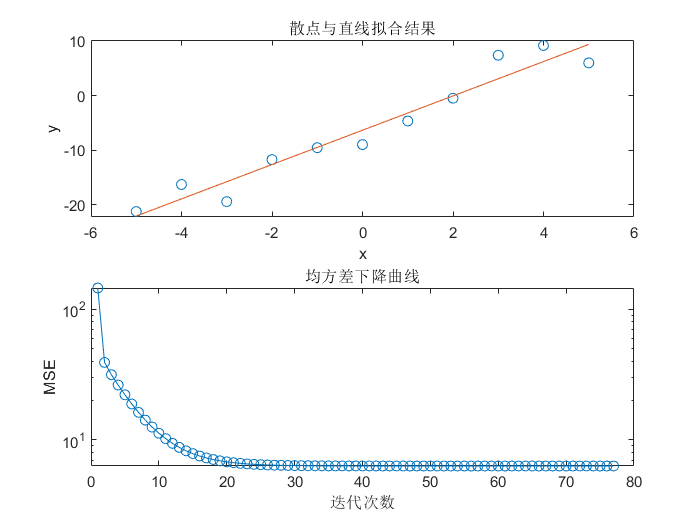

figure;
subplot(2,1,1);                % 绘制散点和直线
plot(P(2,:),d,'o');title('散点与直线拟合结果');
xlabel('x');ylabel('y');
axis([-6,6,min(d)-1,max(d)+1]);
x1=-5:.2:5;
y1=w(1)+w(2)*x1;
hold on;plot(x1,y1);
subplot(2,1,2);                % 绘制均方差下降曲线
semilogy(1:i,ms,'-o');
xlabel('迭代次数');ylabel('MSE');title('均方差下降曲线');

## 最速下降法图意

% 设置步长为0.1，f_change为改变前后的y值变化，仅设置了一个退出条件。
syms x;f=x^2;
step=0.1;x=2;k=0;         %设置步长,初始值,迭代记录数
f_change=x^2;             %初始化差值
f_current=x^2;            %计算当前函数值
figure('color',[1,1,1]);
h=ezplot(@(x,f)f-x^2);    %画出函数图像

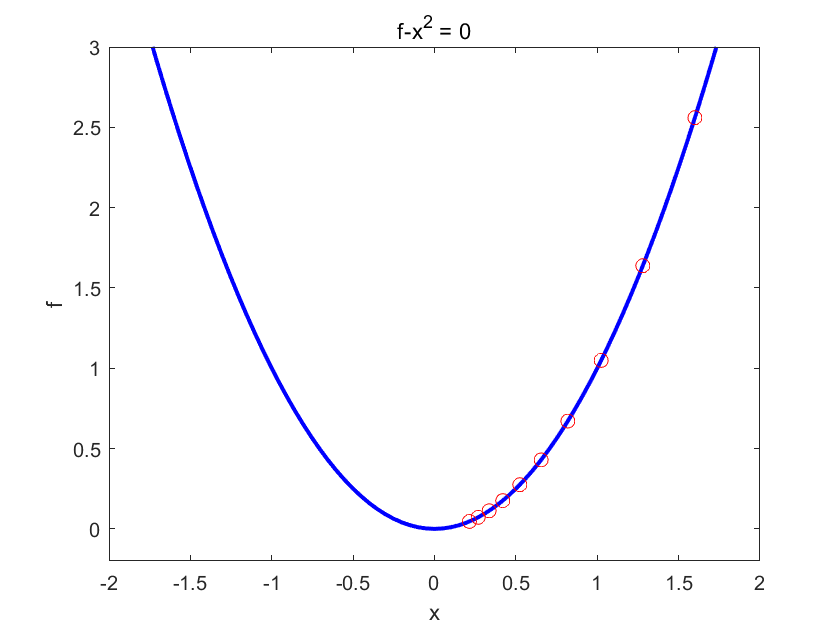

set(h,'LineWidth',2,'LineColor',[0 0 1]);
axis([-2,2,-0.2,3])       %固定坐标轴
hold on

while (f_change>0.000000001 )&&(k<10)     %设置条件，两次计算的值之差小于某个数，跳出循环
    x=x-step*2*x;                         %-2*x为梯度反方向，step为步长，！最速下降法！
    f_change = f_current - x^2;           %计算两次函数值之差
    f_current = x^2 ;                     %重新计算当前的函数值
    plot(x,f_current,'ro','markersize',7) %标记当前的位置
    drawnow;pause(0.2);
    k=k+1;
end
hold off

fprintf('在迭代%d次后找到函数最小值为%e，对应的x值为%e\n',k,x^2,x)

在迭代10次后找到函数最小值为4.611686e-02，对应的x值为2.147484e-01
